# Transformacja ortogonalna obrazu

% load data
img1 = imread('im1.png');
cameraman = imread('cameraman.tif');
img2 = imread('im2.png');

1)

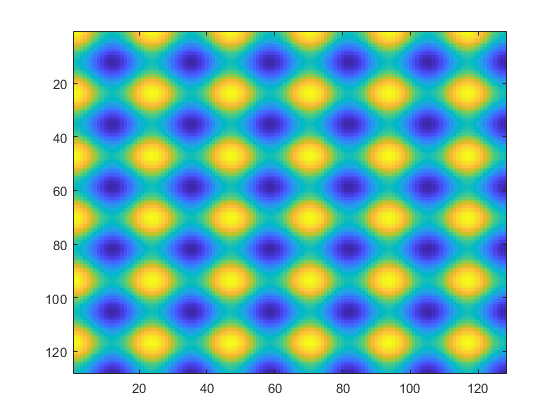

img1_dct2 = dct2(img1);

figure
imagesc(idct2(img1_dct2))

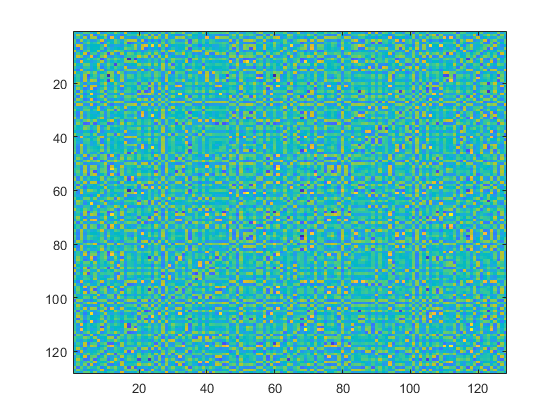


tmp_factor = img1_dct2(1,1);

img1_dct2_zeros = img1_dct2;
img1_dct2_zeros(1:64,1:64) = zeros(64);
img1_dct2_zeros(1,1) = tmp_factor;

figure
imagesc(idct2(img1_dct2_zeros))

2)

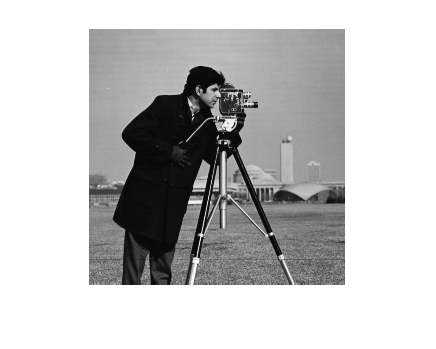

figure
imshow(cameraman)

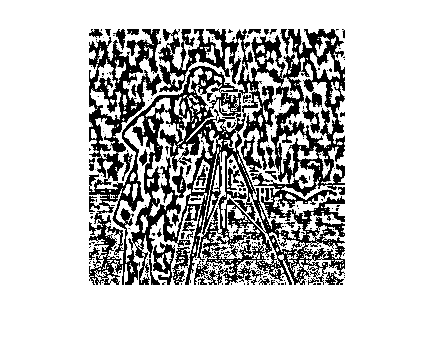


cam_dct2 = dct2(cameraman);

cam_dct_zeros = cam_dct2;
cam_dct_zeros(abs(cam_dct_zeros) > 100) = 0;

figure
imshow(idct2(cam_dct_zeros))

3)

4) 

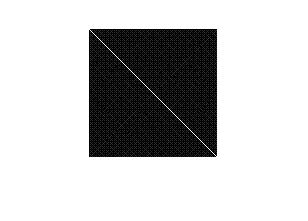

figure; imshow(log(abs(dct2(img2))),[])